cd('C:\Users\PC\Desktop\3081\Content-based-Image-Retrieval')

%CIFAR10
% rootFolder = 'cifar10';
% categories = {'airplane','automobile','bird','cat','deer','dog','frog','horse','ship','truck'};

%CIFAR100
% rootFolder = 'CIFAR-100/MERGED';
% categories = {'keyboard', 'tulip', 'oak_tree', 'turtle', 'mountain', 'pickup_truck', 'clock', 'otter', 'whale', 'lawn_mower', 'girl', 'sunflower', 'elephant', 'tiger', 'plate', 'crocodile', 'butterfly', 'hamster', 'tank', 'orchid', 'snake', 'squirrel', 'lion', 'camel', 'bottle', 'lizard', 'bee', 'maple_tree', 'shark', 'mushroom', 'television', 'rabbit', 'sea', 'house', 'streetcar', 'couch', 'skyscraper', 'shrew', 'beetle', 'pine_tree', 'aquarium_fish', 'leopard', 'lobster', 'telephone', 'raccoon', 'road', 'cattle', 'cloud', 'kangaroo', 'crab', 'castle', 'lamp', 'man', 'bed', 'forest', 'poppy', 'dolphin', 'rocket', 'orange', 'mouse', 'flatfish', 'sweet_pepper', 'baby', 'pear', 'skunk', 'wardrobe', 'porcupine', 'bridge', 'chair', 'can', 'cockroach', 'wolf', 'willow_tree', 'motorcycle', 'snail', 'plain', 'tractor', 'seal', 'trout', 'palm_tree', 'possum', 'worm', 'cup', 'dinosaur', 'fox', 'ray', 'rose', 'bicycle', 'bus', 'table', 'caterpillar', 'boy', 'chimpanzee', 'train', 'bowl', 'woman', 'beaver', 'spider', 'apple', 'bear'};

%COREL80
rootFolder = 'CorelDB';
categories = {'art_dino', 'bld_sculpt', 'obj_aviation', 'obj_car', 'obj_door', 'obj_moleculr', 'pet_cat', 'sc_', 'sc_iceburg', 'sc_rural', 'texture_1', 'texture_6', 'wl_eagle', 'wl_horse', 'wl_owls', 'wl_wolf', 'art_mural', 'eat_drinks', 'obj_balloon', 'obj_cards', 'obj_eastregg', 'obj_orbits', 'pet_dog', 'sc_autumn', 'sc_indoor', 'sc_sunset', 'texture_2', 'wl_buttrfly', 'wl_elephant', 'wl_lepoad', 'wl_porp', 'woman', 'art_1', 'bld_castle', 'eat_feasts', 'obj_bob', 'obj_decoys', 'obj_flags', 'obj_ship', 'pl_flower', 'sc_cloud', 'sc_mountain', 'sc_waterfal', 'texture_3', 'wl_cat', 'wl_fish', 'wl_lion', 'wl_primates', 'art_antiques', 'bld_lighthse', 'fitness', 'obj_bonsai', 'obj_dish', 'obj_mask', 'obj_steameng', 'pl_foliage', 'sc_firewrk', 'sc_night', 'sc_waves', 'texture_4', 'wl_cougr', 'wl_fox', 'wl_lizard', 'wl_roho', 'art_cybr', 'bld_modern', 'obj_234000', 'obj_bus', 'obj_doll', 'obj_mineral', 'obj_train', 'pl_mashroom', 'sc_forests', 'sc_rockform', 'sp_ski', 'texture_5', 'wl_deer', 'wl_goat', 'wl_nests', 'wl_tiger'};

imds = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');
imagesPerClass = 60;
[trainingSet, testingSet] = splitEachLabel(imds, imagesPerClass, 'randomize'); 

featureSet = [];
ref = [];
numImages = numel(trainingSet.Files);

% preprocess the images in the dataset and collect:
% - their SIFT features into the featureSet matrix
% - their original image ID into the ref vector
for i = 1 : numImages
    I = im2gray(readimage(trainingSet,i));
%     I = imresize(I, [256 256]); % can try without this
    sift = detectSIFTFeatures(I).selectStrongest(25);
    [features, sift_points] = extractFeatures(I, sift);
    featureSet = cat(2, featureSet, features.');
    ref = cat(2, ref, repmat([i], 1, size(features,1)));
end


% construct LSH hash tables for featureSet
cd('vLSH')

% Tune hyperparameters
% Q = 144;  % # of queries
K = 32;   % # of nearest neighbors to search for each query
L = 10;   % # of tables
M = 25;   % # of dimensions at projection space
W = 1000; % bucket width
T = 10;   % # of additional probing bins

% Construct index tables
lshStruct = lshConstruct(featureSet, L, M, W);

Creating table 1/10
	Projecting data...
	107072 buckets
	min / max size: 1 / 118
	mean / median: 1.371358e+00 / 1
Creating table 2/10
	Projecting data...
	113249 buckets
	min / max size: 1 / 111
	mean / median: 1.296559e+00 / 1
Creating table 3/10
	Projecting data...
	106461 buckets
	min / max size: 1 / 101
	mean / median: 1.379228e+00 / 1
Creating table 4/10
	Projecting data...
	120138 buckets
	min / max size: 1 / 74
	mean / median: 1.222211e+00 / 1
Creating table 5/10
	Projecting data...
	103762 buckets
	min / max size: 1 / 234
	mean / median: 1.415104e+00 / 1
Creating table 6/10
	Projecting data...
	109104 buckets
	min / max size: 1 / 194
	mean / median: 1.345817e+00 / 1
Creating table 7/10
	Projecting data...
	109662 buckets
	min / max size: 1 / 330
	mean / median: 1.338969e+00 / 1
Creating table 8/10
	Projecting data...
	114699 buckets
	min / max size: 1 / 85
	mean / median: 1.280168e+00 / 1
Creating table 9/10
	Projecting data...
	121492 buckets
	min / max size: 1 / 42
	mean / me

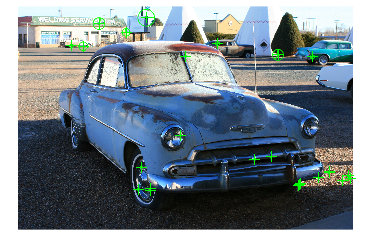

% query an input image
I = imread("car2.jpg");
% I = imresize(I, [256 256]);
figure, imshow(I); hold on;
I = im2gray(I);
sift = detectSIFTFeatures(I).selectStrongest(25);
[queryFeatures, valid_points] = extractFeatures(I, sift);
plot(valid_points,'showOrientation',true);


[idsMULTIPROBE, cand_sizeMULTIPROBE, binsFound_ratiosMULTIPROBE] = lshSearch(queryFeatures.', featureSet, lshStruct, K, T);

Retrieving candidates from table 1
	-----> 0.200614 seconds
Retrieving candidates from table 2
	-----> 0.220782 seconds
Retrieving candidates from table 3
	-----> 0.310375 seconds
Retrieving candidates from table 4
	-----> 0.257554 seconds
Retrieving candidates from table 5
	-----> 0.230316 seconds
Retrieving candidates from table 6
	-----> 0.228575 seconds
Retrieving candidates from table 7
	-----> 0.258975 seconds
Retrieving candidates from table 8
	-----> 0.233297 seconds
Retrieving candidates from table 9
	-----> 0.242459 seconds
Retrieving candidates from table 10
	-----> 0.262039 seconds
Removing duplicate candidates...
	-----> 0.003436 seconds
Performing knn search...
	-----> 0.007313 seconds
Calculating candidate sizes...
	-----> 0.004697 seconds


% convert the feature IDs into their original image IDs
oriImages = zeros(size(idsMULTIPROBE));
for i = 1 : size(idsMULTIPROBE, 1)
    for j = 1 : size(idsMULTIPROBE, 2)
        if idsMULTIPROBE(i, j)>0
          oriImages(i,j) = ref(:,idsMULTIPROBE(i, j));
        end
    end
end

% aggregate and weight the image features by their ranks 
uniqImageIds = unique(oriImages);
N = numel(uniqImageIds);
weights = zeros(N,1);
% fib = zeros(1, K); fib(K-1) = 1;
% for i = K-2:-1:1
%    fib(i) = fib(i+1)+fib(i+2);
% end

for k = 1 : N
    weights(k) = sum(sum(oriImages == uniqImageIds(k))); % unranked weighting of NNs
    % ranked weighting of NNs
    % weights(k) = sum((K + (0 : K - 1) * -1) * (oriImages == uniqImageIds(k)));  % linear
    % weights(k) = sum(flip(exp(1 : K)) * (oriImages == uniqImageIds(k))); % exponential
    % weights(k) = sum(fib * (oriImages == uniqImageIds(k))); % fibonacci
end

ranks = sortrows([weights uniqImageIds], 1, 'descend');


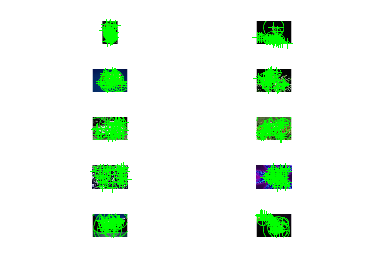

% display top 20 the matching images
figure;
offset = 0;
for pic = 1 : min(11, length(ranks))
    if pic - offset > 10
        break;
    end
    if ranks(pic,2) == 0
        offset = 1;
    end
    if ranks(pic,2)>0
        % plot original image
        I = readimage(trainingSet, ranks(pic, 2));
        subplot(5,2,pic - offset), imshow(I); hold on
        I = im2gray(I);
        sift = detectSIFTFeatures(I).selectStrongest(25);
        [queryFeatures, valid_points] = extractFeatures(I, sift);
        plot(valid_points,'showOrientation',true);
    end
end